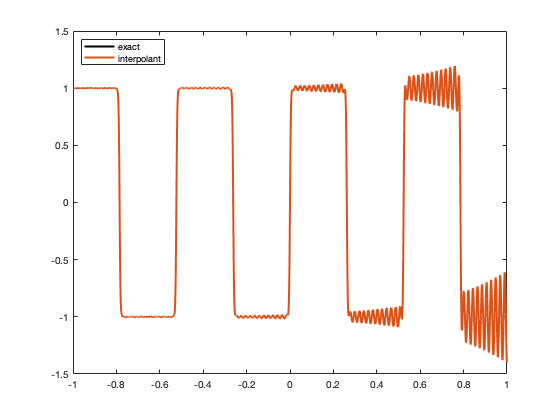

clear, clc, clf
LW = 'linewidth'; lw = 2;

n = 5000;
t = linspace(1, n, n)';
x = @(t)cos(t.*pi./n);
% x = linspace(-1, 1, n)';
m = 10000;
xx = linspace(-1, 1, m)';
F = @(t)tanh(20.*sin(12.*cos(t.*pi./n)))+0.02.*exp(3.*cos(t.*pi./n)).*sin(300.*cos(t.*pi./n));
% F = @sin;
% F = @(x)1./(1+25*x.^2);
f = F(t);
% p = zeros(m, 1);
p1 = zeros(m, 1);
p2 = zeros(m, 1);
R = ones(m, 1);
for j = 2:(n-1)
    p1 = p1 + (((-1)^j).*F(j))./(xx - x(j));
    p2 = p2 + (((-1)^j))./(xx - x(j));
end
p1 = p1 + ((-1).*f(1))./(2.*(xx - 1)) + (((-1)^n).*f(n))./(2.*(xx - x(n)));
p2 = p2 + (-1)./(2.*(xx - 1)) + ((-1)^n)./(2.*(xx - x(n)));
p = p1 ./ p2;
for j = 1:n
    R = R.*(xx - x(j));
end
% for k = 1:n
%     l = ones(m, 1);
%     for j = 1:k-1
%          l = l.*(xx - x(j))/(x(k) - x(j));
%     end
%     for j = k+1:n
%          l = l.*(xx - x(j))/(x(k) - x(j));
%     end
%     p = p + f(k)*l;
%     R = R.*(xx - x(k));
% end
FX = @(x)tanh(20.*sin(12.*x))+0.02.*exp(3.*x).*sin(300.*x);

figure(1)
plot(xx, FX(xx), 'k', LW, lw), hold on
plot(xx, p, LW, lw)
legend('exact', 'interpolant', 'location', 'nw')

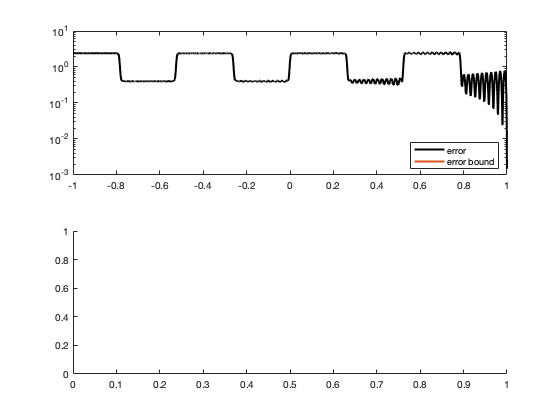

subplot(2,1,1)

figure(2)
plot(2)
semilogy(xx, abs(F(xx) - p), 'k', LW, lw), hold on
semilogy(xx, abs(R)/factorial(n), LW, lw)
legend('error', 'error bound', 'location', 'se')
subplot(2,1,2)